# A Refresher on Function Handles

`15-Nov-2016 : Bradley Horton, bradley.horton@mathworks.com.au`

## Function handles - setting the scene

clear

A Function handle is a data type used to create variables(ie: containers that store things).  However unlike "typical" data types, a function handle variable stores "behaviour" rather than "just" data.  Data can also be stored inside a function handle and we'll look at an example of that shortly.  Function handle variables are used extensively in the following applications:

- solving ODEs

- quadrature

- optimization problems

For example, if you needed to numerically compute $\int_0^{\infty } e^{−x^2 } \ldotp {ln\left(x\right)}^2 dx$, using the `integral()` function, you would create a function handle variable as shown:

fun = @(x) exp(-x.^2).*log(x).^2;

and now we can pass the function handle to the `integral()` function:

q   = integral(fun,0,Inf)

q = 1.9475

## Function handles - Part 1

In the following example we create a function handle variable that stores the behaviour of the `sin()` function:

FH = @sin;   % <----- creating a function handle

Now use it:

A = FH( pi/4 )

A = 0.7071

Now use the function handle variable to create a sine wave:

t  = [ 0: 0.01 : 1 ] ;
y  = FH(2*pi*1*t);     % Use the function handle to Create a sine wave

Plot your data:

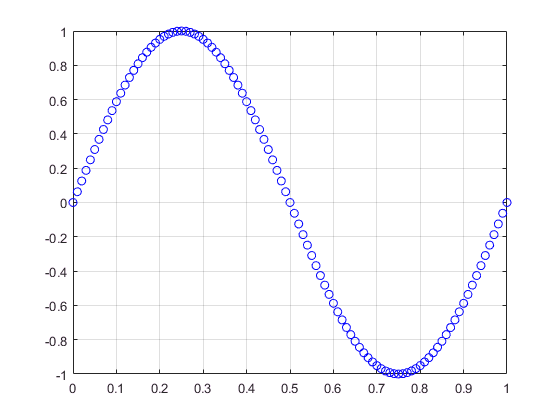

figure;    plot(t,y,'bo');    axis('tight');   grid('on');

## Function handles - part 2, ANONYMOUS

clear

A function handle can also be used to create a variable known as an ANONYMOUS function.  In this case the "functional behaviour" that we're storing, is defined by a mathematical expression.  Let's say that we want to define a parametric equation for a quadratic:

- 
$$y={ax}^{2\text{ }} +bx+c$$


Here's how we can do that by creating an anonymous function handle. ***ATTENTION:  note how we've defined the function using "elementwise" operators such as "***`.^`***" - this will allow us to use our function even when x is a vector.***

FH_2 = @(x, a, b, c) (a*x.^2  + b*x  + c);

Now use it for the case, where:

- x = 100,   a = 1,   b = 2,    c = 3

A = FH_2(100, 1,2,3)

A = 10203

Now use it again

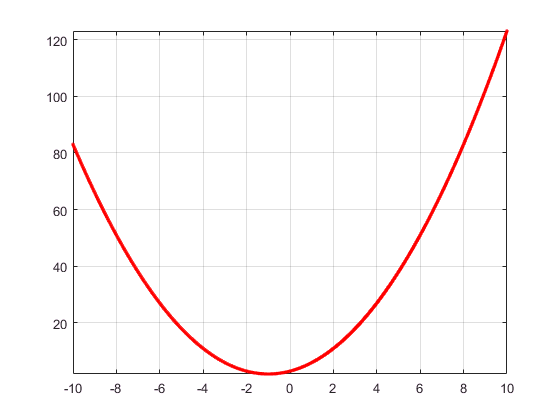

t    = [ -10: 0.01 : 10 ] ;
y2   = FH_2( t, 1,2,3);  

figure;  plot(t,y2,'-r.');   axis('tight');   grid('on');

## Function handles - part 3, ANONYMOUS ... again

clear

An anonymous function handle can also store data.  Observe the following code:

GAIN = 5;
FH   = @(t) ( GAIN * sin(t) );

Now clear the GAIN variable:

clear GAIN
whos

  Name      Size            Bytes  Class              Attributes

  FH        1x1                32  function_handle              



The data that was in the GAIN variable is stored inside the anonymous function:

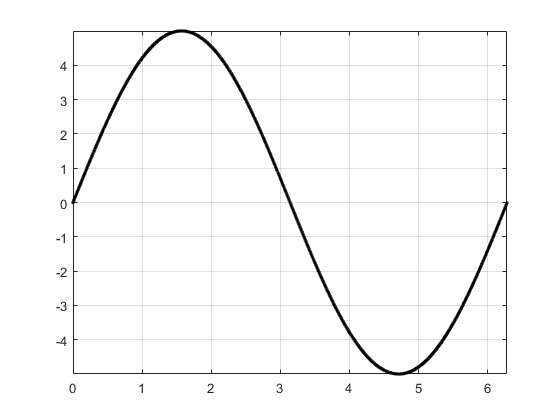

x    = [ 0: 0.01 : 2*pi ] ;
y2   = FH(x);  

figure;  plot(x,y2,'-k.');   
                           axis('tight');   grid('on');

## Function handles - part 4,  .... one more thing !

Another useful application of a function handle is when you've already written a function with a given signature (ie: a specific list of INPUTS) ... but you want "something" to use your function by calling it with a different INPUT order.

Consider the following existing function that already exists:

dbtype brads_funky_func.m


1     function  y = brads_funky_func( c, b, a, x)
2     
3        y = a*x.^2  + b*x  + c;
4     
5     end
6     


Note that the functions signature looks like this:

-   `y = brads_funky_func( c, b, a, x)`

If someone (or something) wanted to call your functoin with the following calling syntax:

- `y = func(x,a,b,c)`

then you could create an anonymous function to accommodate this, ie:

my_FH = @(x,a,b,c) (brads_funky_func( c, b, a, x));

t      = [ -10: 0.01 : 10 ] ;
the_a  = 1;
the_b  = 2;
the_c  = 3

the_c = 3

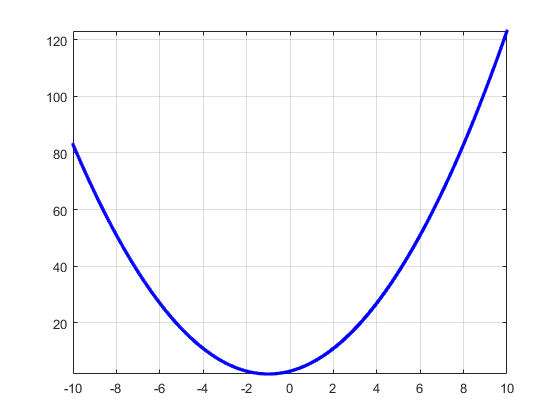

y      = my_FH( t, the_a, the_b, the_c);  

figure;  plot(t,y,'-b.');   axis('tight');   grid('on');

## Function handles - part 5,  .... just remember this

Let's pull together everything that we've just looked at !  

clear all

Say we have a function that looks like this:

dbtype brads_other_funky_func.m


1     function  y = brads_other_funky_func( a, x, t)
2     
3        y = (a * t)  +  x;
4     
5     end
6     


Create a local variable:

MY_A = 10;

Create a function handle with a specified calling syntax:

FH = @(t,x) (brads_other_funky_func( MY_A, x, t));

And use the function handle:

the_t = 2;
the_x = 3;
y     = FH(the_t, the_x)

y = 23